## 题目1

A = rand(1,3000);
m = mean(A)

m = 0.5038

D = var(A)

D = 0.0818

Max = max(A)

Max = 0.9998

Min = min(A)

Min = 3.4146e-04

precent = length(A(A>0.5))/length(A)

precent = 0.5100

## 题目2

line = 100;
Stu = zeros(line,6);
Stu(:,1) = 1:line;
Stu(:,2:end) = randi([45,95],line,5);
disp(Stu);

     1    64    93    57    72    81
     2    61    72    64    65    51
     3    95    57    67    50    67
     4    81    74    87    81    70
     5    66    91    87    76    72
     6    50    90    68    84    88
     7    82    69    64    73    79
     8    77    67    92    86    86
     9    48    60    82    74    72
    10    51    47    82    93    93
    11    95    83    93    89    48
    12    70    51    71    70    72
    13    46    63    85    85    59
    14    47    65    68    69    69
    15    52    90    88    87    79
    16    90    46    64    61    55
    17    68    88    82    94    76
    18    73    59    94    59    61
    19    70    57    71    48    89
    20    48    69    66    83    51
    21    90    82    55    87    50
    22    59    55    61    92    93
    23    58    56    50    61    52
    24    75    94    64    86    52
    25    69    75    61    72    52
    26    63    60    62    68    49
    27    78    94    86    86    68
 

[maxValues,maxrowIndices] = max(Stu(:,2:end));
[minValues,minrowIndices] = min(Stu(:,2:end));
kemu=["语文:", "数学:","英语:" ,"体育:" ,"文综理综:"];
% (1)
fprintf("每门科目的最高分分别为：")

每门科目的最高分分别为：

disp(kemu+maxValues);

    "语文:95"    "数学:95"    "英语:95"    "体育:95"    "文综理综:95"



fprintf("每门科目的最高分序号分别为：")

每门科目的最高分序号分别为：

disp(kemu+maxrowIndices);

    "语文:3"    "数学:54"    "英语:90"    "体育:35"    "文综理综:69"




fprintf("每门科目的最低分分别为：")

每门科目的最低分分别为：

disp(kemu+minValues);

    "语文:45"    "数学:45"    "英语:45"    "体育:45"    "文综理综:46"



fprintf("每门科目的最低分序号分别为：")

每门科目的最低分序号分别为：

disp(kemu+minrowIndices);

    "语文:80"    "数学:30"    "英语:49"    "体育:77"    "文综理综:70"




%(2)
fprintf("每门科目的平均分分别为：")

每门科目的平均分分别为：

disp(kemu+mean(Stu(:,2:end)));

    "语文:68.53"    "数学:70.32"    "英语:71.27"    "体育:72.33"    "文综理综:69.7"



fprintf("每门科目的方差分别为：")

每门科目的方差分别为：

disp(kemu+var(Stu(:,2:end)));

    "语文:209.3223"    "数学:249.6137"    "英语:188.3203"    "体育:190.6072"    "文综理综:198.1515"




%(3)
[val,num_stu] = max(sum(Stu(:,2:end),2));
fprintf("最高分为 %d ,学生序号为 %d",val,num_stu);

最高分为 431 ,学生序号为 57


%(4)
total = [Stu(:,1),sum(Stu(:,2:end),2)];
total_fix = sortrows(total,2,"descend");
zcj = total_fix(:,1)

zcj =     57
    93
    28
    92
    27
    48
    86
     8
    11
    17


xsxh = total_fix(:,2)

xsxh =    431
   431
   426
   414
   412
   411
   411
   408
   408
   408


## 题目3

time = [6, 8, 10, 12, 14, 16, 18]; 
indoor_temp = [18.0, 20.0, 22.0, 24.0, 26.0, 28.0, 32.0]; % 室内温度
outdoor_temp = [15.0, 19.0, 22.0, 25.0, 30.0, 31.0, 32.0]; % 室外温度
% 插值时间
interp_time = 6.5:2:17.5;
% 三次样条插值
indoor_interp = spline(time, indoor_temp, interp_time);
outdoor_interp = spline(time, outdoor_temp, interp_time);

% 显示插值结果
fprintf('插值时间点：\n');

插值时间点：


disp(interp_time);

    6.5000    8.5000   10.5000   12.5000   14.5000   16.5000



fprintf('室内温度插值结果：\n');

室内温度插值结果：


disp(indoor_interp);

   18.4980   20.5014   22.4964   24.5131   26.4512   28.7134



fprintf('室外温度插值结果：\n');

室外温度插值结果：


disp(outdoor_interp);

   16.0928   19.8444   22.6076   26.2566   30.6475   30.9661



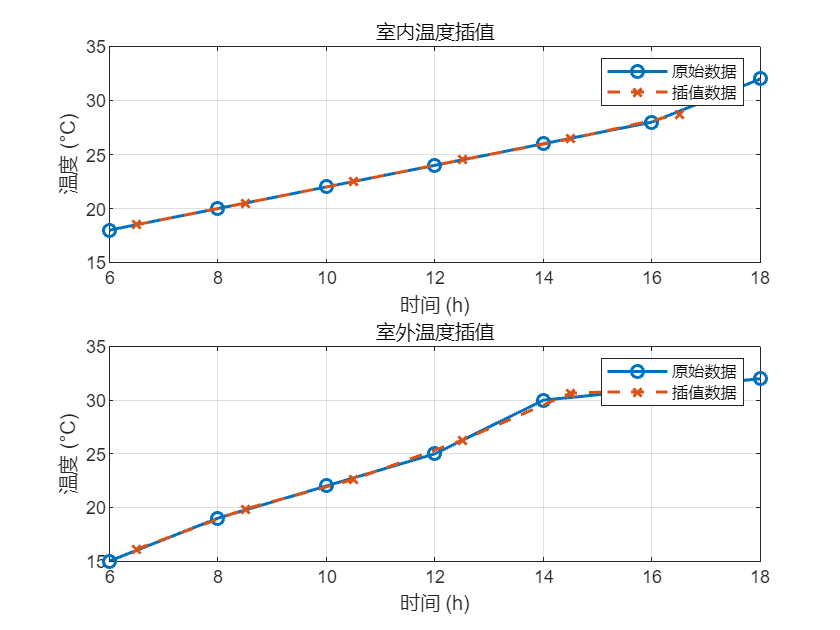


% 绘制插值曲线
figure;
subplot(2, 1, 1);
plot(time, indoor_temp, 'o-', 'LineWidth', 1.5);
hold on;
plot(interp_time, indoor_interp, 'x--', 'LineWidth', 1.5);
title('室内温度插值');
xlabel('时间 (h)');
ylabel('温度 (°C)');
legend('原始数据', '插值数据');
grid on;

subplot(2, 1, 2);
plot(time, outdoor_temp, 'o-', 'LineWidth', 1.5);
hold on;
plot(interp_time, outdoor_interp, 'x--', 'LineWidth', 1.5);
title('室外温度插值');
xlabel('时间 (h)');
ylabel('温度 (°C)');
legend('原始数据', '插值数据');
grid on;

## 题目4

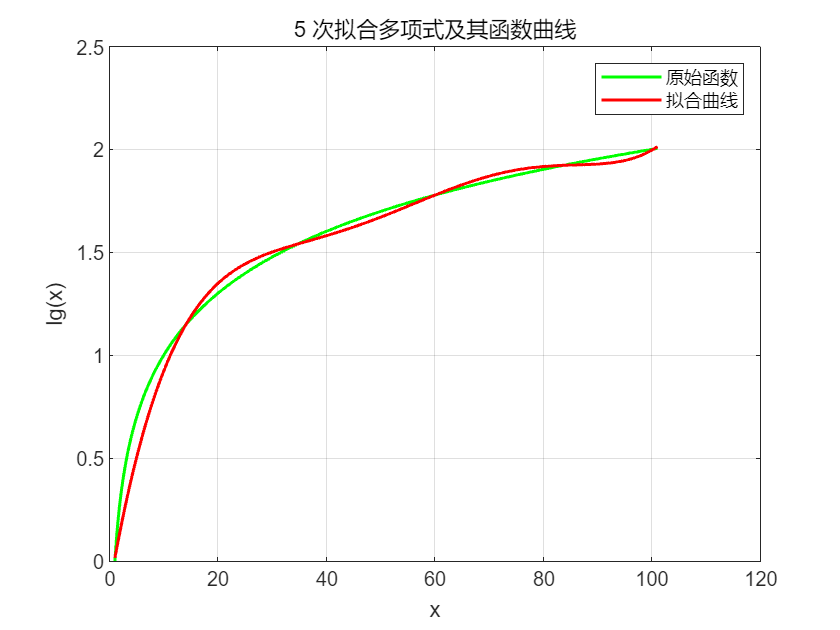

% 5 次拟合多项式
x = [1, 11, 21, 31, 41, 51, 61, 71, 81, 91, 101];
lgx = [0, 1.0414, 1.3222, 1.4914, 1.6128, 1.7076, 1.7853, 1.8513, 1.9085, 1.9590, 2.0043];
p = polyfit(x, lgx, 5);

% 生成拟合曲线
x_fine = linspace(1, 101, 500);
lgx_fine = polyval(p, x_fine);
lgx_true = log10(x_fine);
% 绘制拟合曲线
figure;
plot(x_fine, lgx_true, 'g-', 'LineWidth', 1.5); % 原始数据点
hold on;
plot(x_fine, lgx_fine, 'r-', 'LineWidth', 1.5); % 拟合曲线
title('5 次拟合多项式及其函数曲线');
xlabel('x');
ylabel('lg(x)');
legend('原始函数', '拟合曲线');
grid on;


fprintf('5 次拟合多项式的系数：\n');

5 次拟合多项式的系数：


disp(p);

    0.0000   -0.0000    0.0001   -0.0058    0.1537   -0.1326



## 第五题

clc;
clear;
% 多项式函数定义
P1 = @(x) x.^4 + 2.*x.^3 + 4.*x.^2 + 5;
P2 = @(x) x + 2;
P3 = @(x) x.^2 + 2.*x + 3;
% (1)
P = @(x) P1(x) + P2(x)*P3(x);
% (2)求根
roots = roots([1 2 4 5]);
fprintf('P(x) 的根为:');

P(x) 的根为:

disp(roots);

  -1.5260 + 0.0000i
  -0.2370 + 1.7946i
  -0.2370 - 1.7946i



% (3)
A = [-1 1.2 -1.4; 0.75 2 3.5; 0 5 2.5];
P_A = zeros(size(A));
for i = 1:numel(A)%A里的循环
    P_A(i) = P(A(i));
end
fprintf('当 x 取矩阵 A 的每一个元素时, P(x) 的值为:');

当 x 取矩阵 A 的每一个元素时, P(x) 的值为:

disp(P_A);

   1.0e+03 *

    0.0100    0.0382    0.0125
    0.0223    0.0970    0.4122
    0.0110    1.2460    0.1644



% (4)
P_A = P(A);
fprintf('当以矩阵 A 为自变量时, P(x) 的值为:');

当以矩阵 A 为自变量时, P(x) 的值为:

disp(P_A);

   1.0e+03 *

    0.0280    0.0811    0.0931
    0.0507    0.3248    0.4631
    0.0579    1.2417    0.3245

